clc;
clear;
addpath(genpath(pwd));

## 1.Empirical constants

A1   = 0.3         ; A2   = 0.3        ;
b1   = 0.3        ; b2   = 0.3           ;
Tp   = 5           ; Tf0  = 1             ;
Tvl  = 8            ; Tv0  = 2             ;
st   = 0.19          ; yita = 0.95          ;

% A1 =0.0413173
% b1 =0.243680
% A2 =0.408737
% b2 =0.222466
% Tp =6
% Tf0 =0.130371
% Tvl =14.465300
% Tv0 =10.000000
% yita =0.873809

A3   = 0.2           ; b3   = 0.2           ;
A4   = 0.1           ; b4   = 0.1           ;
A5   = 1             ; b5   = 5             ;
S1   = 2             ; S2   = 5             ;
S3   = 2             ; S4   = 5             ;
k0   = 0             ; k1   = -0.001        ;
k2   = -0.025        ; k3   = -0.07         ;

param = [A1,b1,A2,b2,...
        Tp,Tf0,Tvl,Tv0,...
        yita];

## 2.Operating condition setup

%% ==================== 1. Operating condition setup ============================
meanangle    = -9.4;
averageangle = 7;
conditions   = input_condition(meanangle,averageangle);
airfoildata  = input_afdata;

CFDdatapath = resolve_data_file('re5e5_i9.4_f2.4.txt', 'cfd');
data    = readmatrix(resolve_data_file('FFA_W3_211.txt', 'airfoil'));

%% ==================== 2. Collect variables ============================
setcase.meanangle    = meanangle;
setcase.averageangle = averageangle;
setcase.conditions   = conditions;
setcase.airfoldata   = airfoildata;
setcase.CFDdatapath  = CFDdatapath;

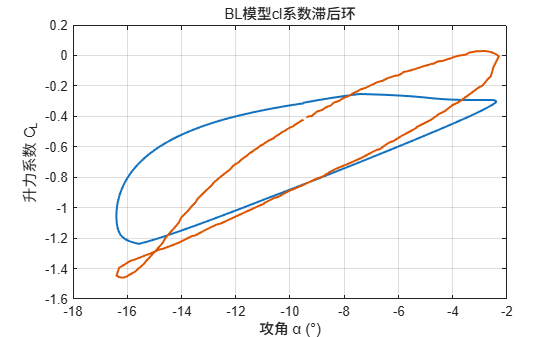

[CC_total,CN_total,CM_total,CD,CL,CM,a] = cal_DS(param,conditions,airfoildata);
[a0, cl] = get_CFDdata(CFDdatapath,setcase);
w = conditions.w;
dt = conditions.dt;
start = 7;
last  = 8;
idx_s = fix(2*pi/w*start/dt);
idx_l = fix(2*pi/w*last/dt);

plot(rad2deg(a(idx_s:idx_l)), CN_total(idx_s:idx_l), a0,cl,'LineWidth',1.5);
xlabel('angle of attack α (°)'); ylabel('lift coefficient C_L');
title('BLmodelclcoefficient hysteresis loop'); grid on;

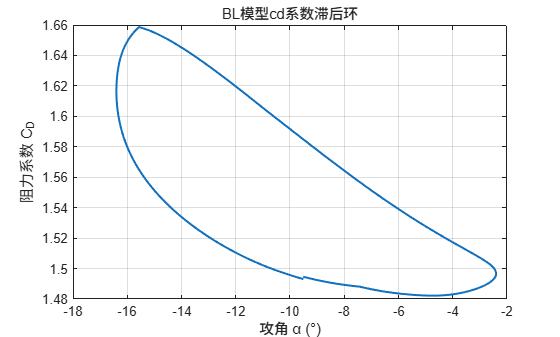



plot(rad2deg(a(idx_s:idx_l)), CD(idx_s:idx_l), 'LineWidth',1.5);
xlabel('angle of attack α (°)'); ylabel('drag coefficient C_D');
title('BLmodelcdcoefficient hysteresis loop');grid on;

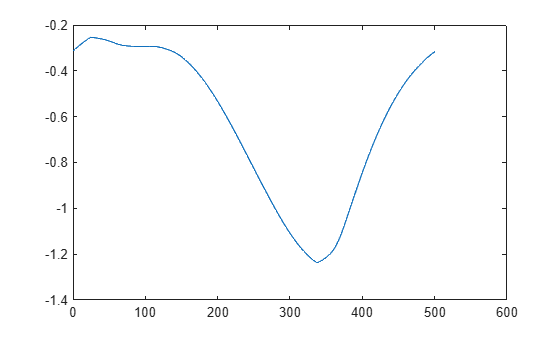


plot(CN_total(idx_s:idx_l))

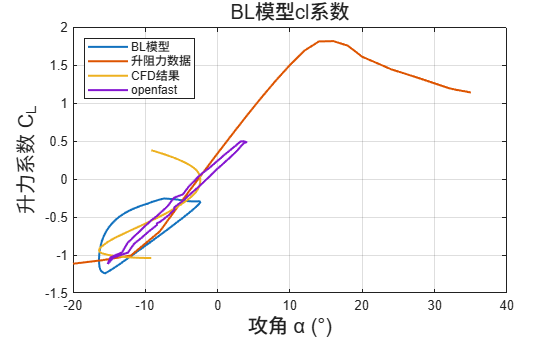


%openfastdata----------------------------------------------

fastcl = readmatrix("openfast_1hz_5_cl.txt");
fastcl(:,2) = smooth(fastcl(:,2));
fast_a1 = fastcl(:,1);
fast_cl = fastcl(:,2);

fastcd = readmatrix("openfast_1hz_5_cd.txt");
fastcd(:,2) = smooth(fastcd(:,2));
fast_a2 = fastcd(:,1);
fast_cd = fastcd(:,2);

%CFDdata---------------------------------------------------

[a1,cl] = drawCoffeint('cl_211_0.31_-5.out',setcase);
plot(rad2deg(a(idx_s:idx_l)), CL(idx_s:idx_l),data(43:72,1),data(43:72,2),a1,cl,fast_a1,fast_cl, 'LineWidth',1.5);
xlabel('angle of attack α (°)','FontSize',15); 
ylabel('lift coefficient C_L','FontSize',15);
title('BLmodelclcoefficient','FontSize',15); grid on;
legend('BLmodel','lift-drag data','CFDresult','openfast','Location','northwest')
saveas(gcf, ['cl_compare','.png']);
exportgraphics(gcf,'cl_compare.pdf','ContentType', 'vector')

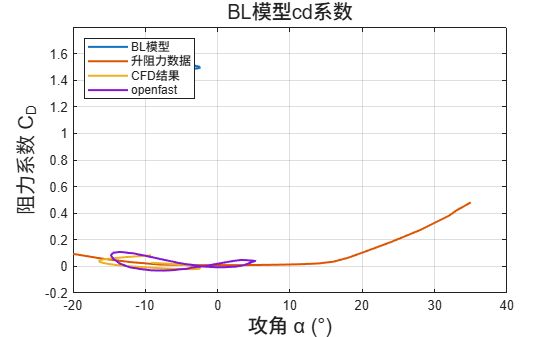


[a2,cd] = drawCoffeint('cd_211_0.31_-5.out',setcase);
plot(rad2deg(a(idx_s:idx_l)), CD(idx_s:idx_l), data(43:72,1),data(43:72,3),a2,cd,fast_a2,fast_cd,'LineWidth',1.5);
xlabel('angle of attack α (°)','FontSize',15); 
ylabel('drag coefficient C_D','FontSize',15);
title('BLmodelcdcoefficient','FontSize',15); grid on;
legend('BLmodel','lift-drag data','CFDresult','openfast','Location','northwest')
saveas(gcf, ['cd_compare','.png']);
exportgraphics(gcf,'cd_compare.pdf','ContentType', 'vector')

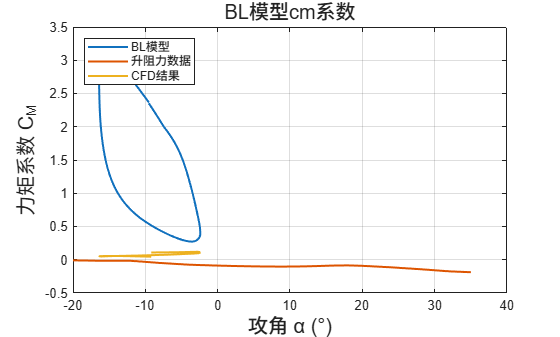


[a3,cm] = drawCoffeint('cm_211_0.31_-5.out',setcase);
plot(rad2deg(a(idx_s:idx_l)), CM_total(idx_s:idx_l),data(43:72,1),data(43:72,4),a3,cm, 'LineWidth',1.5);
xlabel('angle of attack α (°)','FontSize',15); 
ylabel('moment coefficient C_M','FontSize',15);
title('BLmodelcmcoefficient','FontSize',15); grid on;
legend('BLmodel','lift-drag data','CFDresult','Location','northwest')
saveas(gcf, ['cm_compare','.png']);
exportgraphics(gcf,'cm_compare.pdf','ContentType', 'vector')